# Stock Prediction via STKD

The information shared on social media generates sentiments and reactions in investors that influence their decisions to buy or sell financial assets, especially on the stock market [1]. News shared on social media, whether true or not, cause changes in the trends of international stock market indices [2]. Some studies confirm the relationship between sentiments generated by social media in investors and market trends, and the current study continues this path in exploring pandemic periods with a lexicon-based approach to detect polarity in financial news on Twitter.

Our hypothesis is that sentiments expressed via Tweets and News can cause a potential change in stock and could be a crucial factor for predicting very volatile prices such as **Cryptocurrency**.In the recent times, we saw hoe Elon Musks Tweets single handed brought down the price of Bitcoin and sky-rocketted Dogecoin's price.

In the experiment performed we will be collecting News and Tweets and analysiong the sentiments of the same which will act as the spatial component of our analysis and temporal being time.

### Bitcoin prediction with Tweets

For this experiment tweets between 6th February to 24th April 2021 were collected along with the closing price of Bitcoin in the same Date range. The collected tweet swill have numerous tweets for any given day hence an mean of all the sentiments for the day was taken.

The sentiment analysis was done in python using *'nlptown/bert-base-multilingual-uncased-sentiment' *

*The above code corresponds to the pythonb scrip for extracting sentiments.*

SInce the data isnt very huge, a single snapshot will will very sparse.

clc
clear all
close all

load sent_snp.mat
V = sent;
s = size(V);
Time = linspace(0,1,s(2));
Exis = linspace(0,1,s(1));


% APPLY STKD TO V
[J,K]=size(V);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%% STKD  PARAMETERS %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% SET PARAMETERS STKD
% Tolerances
% SVD
varepsilon1=1e-8;
% DMD
varepsilon2=1e-7;
% Set index d: dSpace for spatial analysis and dTime for temporal analysis
dSpace=2;
dTime=1;

[Vreconst,Modes,Amplitudes,Amplitudesx,GrowthRatex,Frequencyx,Amplitudest,GrowthRatet,Frequencyt]=...
CalculateDMDdSdT(dSpace,dTime,Time,Exis,V,varepsilon1,varepsilon2);

Spatial Dimension: singular values
    18

Spatial dimension reduction
    20



size of a


ans =     20     1


size of Q


ans =     18    20


Spectral complexity
    20



ans = 'Spectral complexity'

kk3 = 18

   360

   360

Number of spatial modes
    20

Number of temporal modes
    18




% CALCULATE RRMS ERROR
dif=Vreconst-V;
errorRMS=norm(dif(:))/norm(V(:));
disp('Reconstruction error: RRMSE')

Reconstruction error: RRMSE


disp(errorRMS)

    0.9540



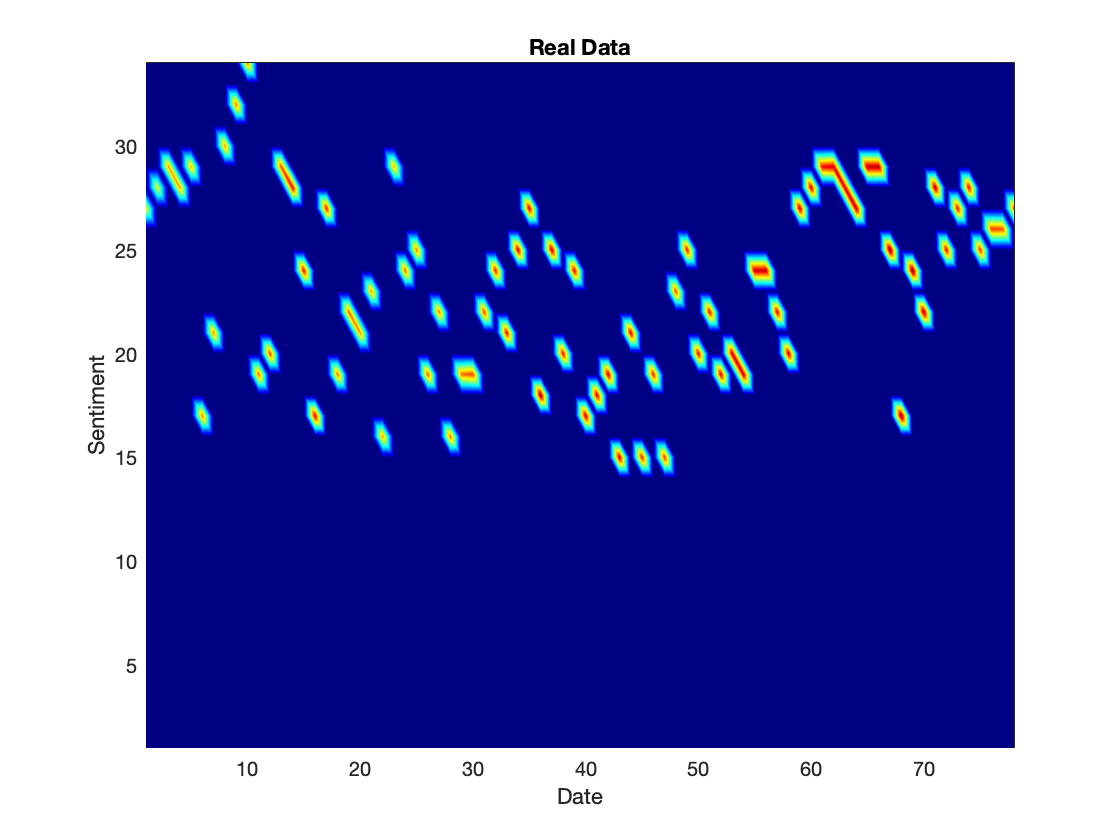

% PLOT RECONSTRUCTION
figure
pcolor(V)
shading('interp')
colormap(jet)
xlabel('Date')
ylabel('Sentiment')
title("Real Data")

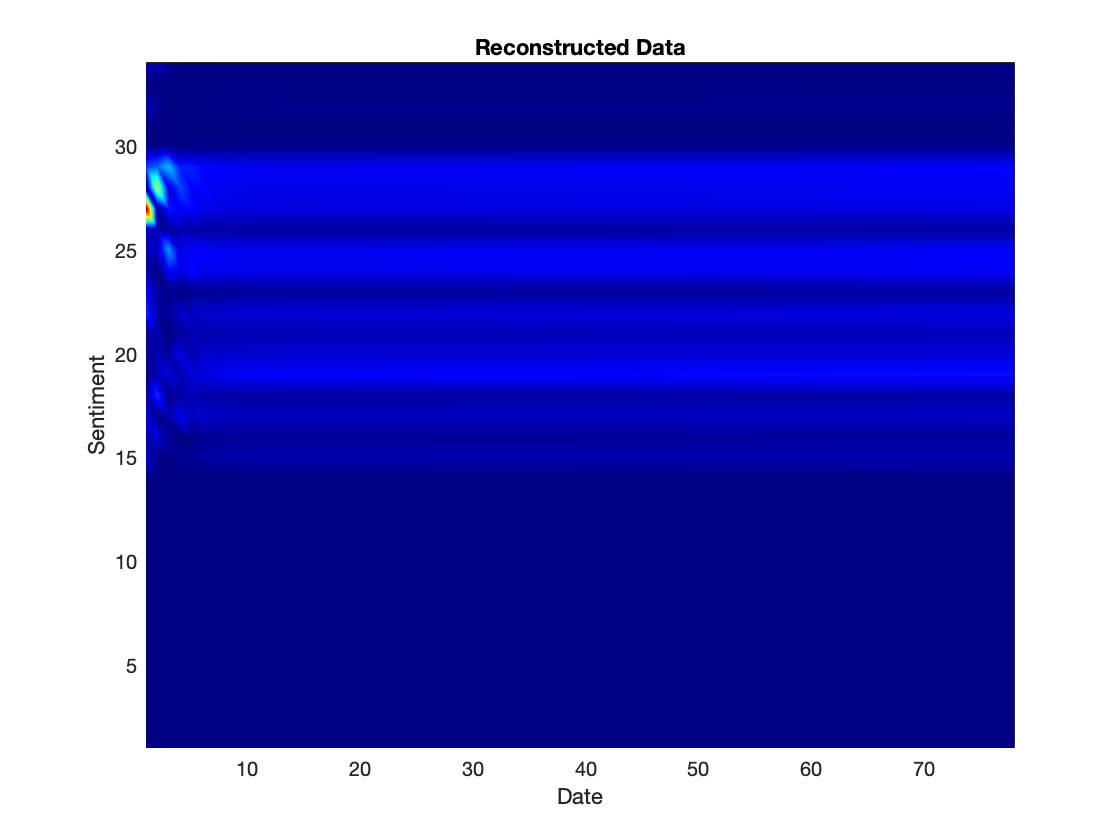


h9=figure;
axes9 = axes('Parent',h9,'FontSize',14,'FontName','Agency FB');
box(axes9,'on');
pcolor(abs(Vreconst))
shading('interp')
colormap(jet)
xlabel('Date')
ylabel('Sentiment')
title("Reconstructed Data")

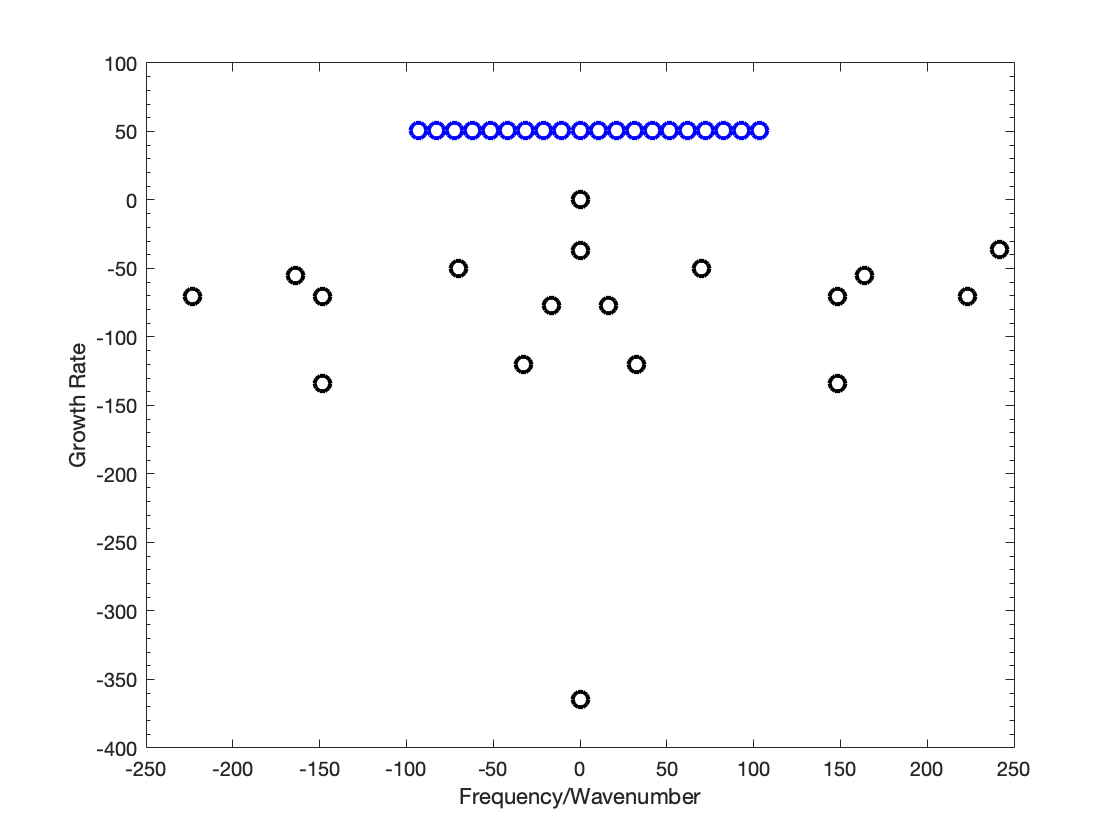

% Plot: frequency/wavenumber vs. amplitude, vs. growth rate
figure1 = figure;
axes1 = axes('Parent',figure1);
hold(axes1,'on');
box(axes1,'on');
semilogy(Frequencyt,GrowthRatet,'o','linewidth',2,'color','k','MarkerSize',8);
semilogy(Frequencyx,GrowthRatex,'o','linewidth',2,'color','b','MarkerSize',8);
set(axes1,'YMinorTick','on');
xlabel('Frequency/Wavenumber')
ylabel('Growth Rate')

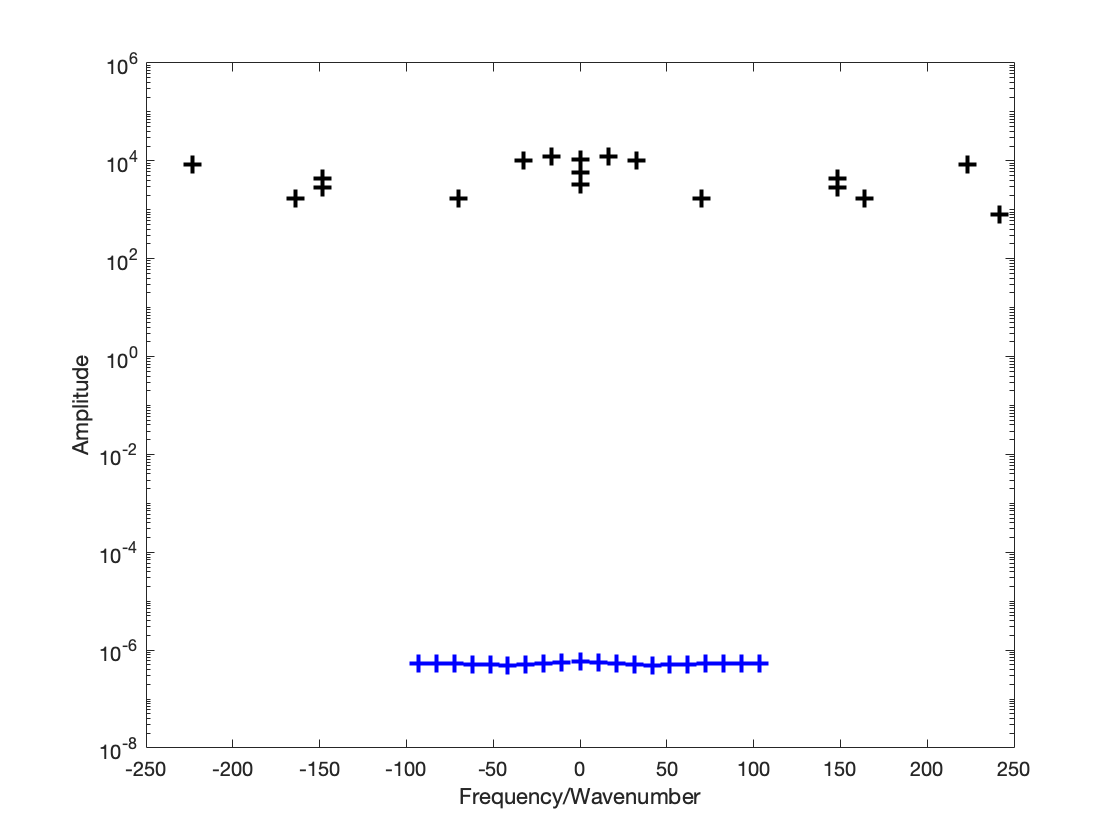



figure1 = figure;
axes1 = axes('Parent',figure1);
hold(axes1,'on');
box(axes1,'on');
semilogy(Frequencyt,Amplitudest,'+','linewidth',2,'color','k','MarkerSize',8);
semilogy(Frequencyx,Amplitudesx,'+','linewidth',2,'color','b','MarkerSize',8);
set(axes1,'YMinorTick','on','YScale','log');
xlabel('Frequency/Wavenumber')
ylabel('Amplitude')

figure

### Dogecoin prediction with News Sentiments

Similar to the Bitcoin approach, news was collected for the past 2 years -  1st January 2019 to 3rd June 2021. 

`The full notebook can be found here : `[https://colab.research.google.com/drive/1YeivODqLAZtZiSBbuot7vV_T8ZkFzwEF?usp=sharing](https://colab.research.google.com/drive/1YeivODqLAZtZiSBbuot7vV_T8ZkFzwEF?usp=sharing)

clear all
close all
clc
%Import data from text file
% Script for importing data from the following text file:
%
%    filename: /Volumes/Rohith/College/SpatioTemporalKoopman/scripts/Matrix.csv
%
% Auto-generated by MATLAB on 02-Jun-2021 23:38:47

% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 304);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["e00", "e00_1", "e00_2", "e00_3", "e00_4", "e00_5", "e00_6", "e00_7", "e00_8", "e00_9", "e00_10", "e00_11", "e00_12", "e00_13", "e00_14", "e00_15", "e00_16", "e00_17", "e00_18", "e00_19", "e00_20", "e00_21", "e00_22", "e00_23", "e00_24", "e00_25", "e00_26", "e00_27", "e00_28", "e00_29", "e00_30", "e00_31", "e00_32", "e00_33", "e00_34", "e00_35", "e00_36", "e00_37", "e00_38", "e00_39", "e00_40", "e00_41", "e00_42", "e00_43", "e00_44", "e00_45", "e00_46", "e00_47", "e00_48", "e00_49", "e00_50", "e00_51", "e00_52", "e00_53", "e00_54", "e00_55", "e00_56", "e00_57", "e00_58", "e00_59", "e00_60", "e00_61", "e00_62", "e00_63", "e00_64", "e00_65", "e00_66", "e00_67", "e00_68", "e00_69", "e00_70", "e00_71", "e00_72", "e00_73", "e00_74", "e00_75", "e00_76", "e00_77", "e00_78", "e00_79", "e00_80", "e00_81", "e00_82", "e00_83", "e00_84", "e00_85", "e00_86", "e00_87", "e00_88", "e00_89", "e00_90", "e00_91", "e00_92", "e00_93", "e00_94", "e00_95", "e00_96", "e00_97", "e00_98", "e00_99", "e00_100", "e00_101", "e00_102", "e00_103", "e00_104", "e00_105", "e00_106", "e00_107", "e00_108", "e00_109", "e00_110", "e00_111", "e00_112", "e00_113", "e00_114", "e00_115", "e00_116", "e00_117", "e00_118", "e00_119", "e00_120", "e00_121", "e00_122", "e00_123", "e00_124", "e00_125", "e00_126", "e00_127", "e00_128", "e00_129", "e00_130", "e00_131", "e00_132", "e00_133", "e00_134", "e00_135", "e00_136", "e00_137", "e00_138", "e00_139", "e00_140", "e00_141", "e00_142", "e00_143", "e00_144", "e00_145", "e00_146", "e00_147", "e00_148", "e00_149", "e00_150", "e00_151", "e00_152", "e00_153", "e00_154", "e00_155", "e00_156", "e00_157", "e00_158", "e00_159", "e00_160", "e00_161", "e00_162", "e00_163", "e00_164", "e00_165", "e00_166", "e00_167", "e00_168", "e00_169", "e00_170", "e00_171", "e00_172", "e00_173", "e00_174", "e00_175", "e00_176", "e00_177", "e00_178", "e00_179", "e00_180", "e00_181", "e00_182", "e00_183", "e00_184", "e00_185", "e00_186", "e00_187", "e00_188", "e00_189", "e00_190", "e00_191", "e00_192", "e00_193", "e00_194", "e00_195", "e00_196", "e00_197", "e00_198", "e00_199", "e00_200", "e00_201", "e00_202", "e00_203", "e00_204", "e00_205", "e00_206", "e00_207", "e00_208", "e00_209", "e00_210", "e00_211", "e00_212", "e00_213", "e00_214", "e00_215", "e00_216", "e00_217", "e00_218", "e00_219", "e00_220", "e00_221", "e00_222", "e00_223", "e00_224", "e00_225", "e00_226", "e00_227", "e00_228", "e00_229", "e00_230", "e00_231", "e00_232", "e00_233", "e00_234", "e00_235", "e00_236", "e00_237", "e00_238", "e00_239", "e00_240", "e00_241", "e00_242", "e00_243", "e00_244", "e00_245", "e00_246", "e00_247", "e00_248", "e00_249", "e00_250", "e00_251", "e00_252", "e00_253", "e00_254", "e00_255", "e00_256", "e00_257", "e00_258", "e00_259", "e00_260", "e00_261", "e00_262", "e00_263", "e00_264", "e00_265", "e00_266", "e00_267", "e00_268", "e00_269", "e00_270", "e00_271", "e00_272", "e00_273", "e00_274", "e00_275", "e00_276", "e00_277", "e00_278", "e00_279", "e00_280", "e00_281", "e00_282", "e00_283", "e00_284", "e00_285", "e00_286", "e00_287", "e00_288", "e00_289", "e00_290", "e00_291", "e00_292", "e00_293", "e00_294", "e00_295", "e00_296", "e00_297", "e00_298", "e00_299", "e00_300", "e00_301", "e00_302", "e00_303"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
Matrix = readtable("/Volumes/Rohith/College/SpatioTemporalKoopman/scripts/Matrix.csv", opts);

% Convert to output type
Matrix = table2array(Matrix);

% Clear temporary variables
clear opts

V = 100*Matrix;
s = size(V);
Time = linspace(0,1,s(2));
Exis = linspace(0,1,s(1));



% APPLY STKD TO V
[J,K]=size(V);
for i=1:J
    for j = 1:K
        if(isnan(V(i,j)))
           V(i,j) = 0;
        end
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%% STKD  PARAMETERS %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% SET PARAMETERS STKD
% Tolerances
% SVD
varepsilon1=1e-20;
% DMD
varepsilon2=1e-18;
% Set index d: dSpace for spatial analysis and dTime for temporal analysis
dSpace=25;
dTime=25;

[Vreconst,Modes,Amplitudes,Amplitudesx,GrowthRatex,Frequencyx,Amplitudest,GrowthRatet,Frequencyt]=...
CalculateDMDdSdT(dSpace,dTime,Time,Exis,V,varepsilon1,varepsilon2);

Spatial Dimension: singular values
    50

Spatial dimension reduction
    26

size of a


ans =     26     1


size of Q


ans =     50    26


Spectral complexity
    26

Spatial dimension reduction
   280

size of a


ans =    280     1


size of Q


ans =     50   280


Spectral complexity
   280



        7280

        7280

Number of spatial modes
    26

Number of temporal modes
   280




% CALCULATE RRMS ERROR
dif=Vreconst-V;
errorRMS=norm(dif(:))/norm(V(:));
disp('Reconstruction error: RRMSE')

Reconstruction error: RRMSE


disp(errorRMS)

    0.9998



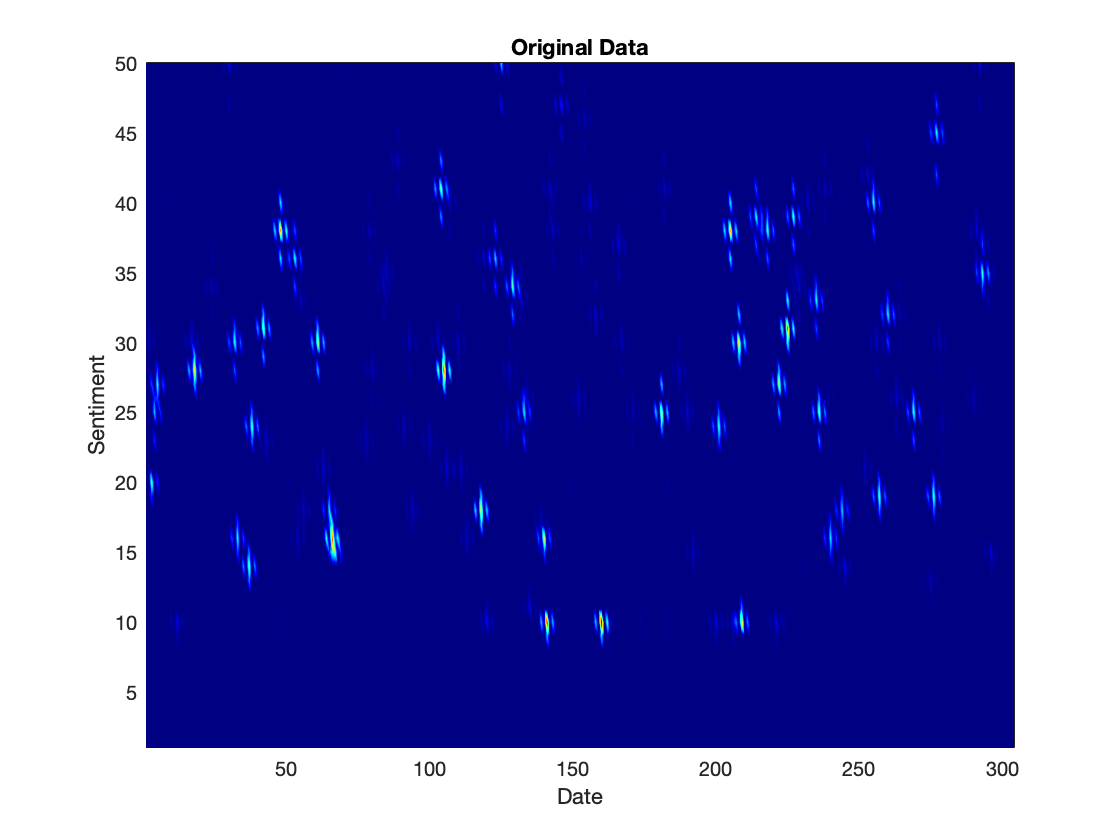

% PLOT RECONSTRUCTION
figure
pcolor(V)
shading('interp')
colormap(jet)
xlabel('Date')
ylabel('Sentiment')
title("Original Data")

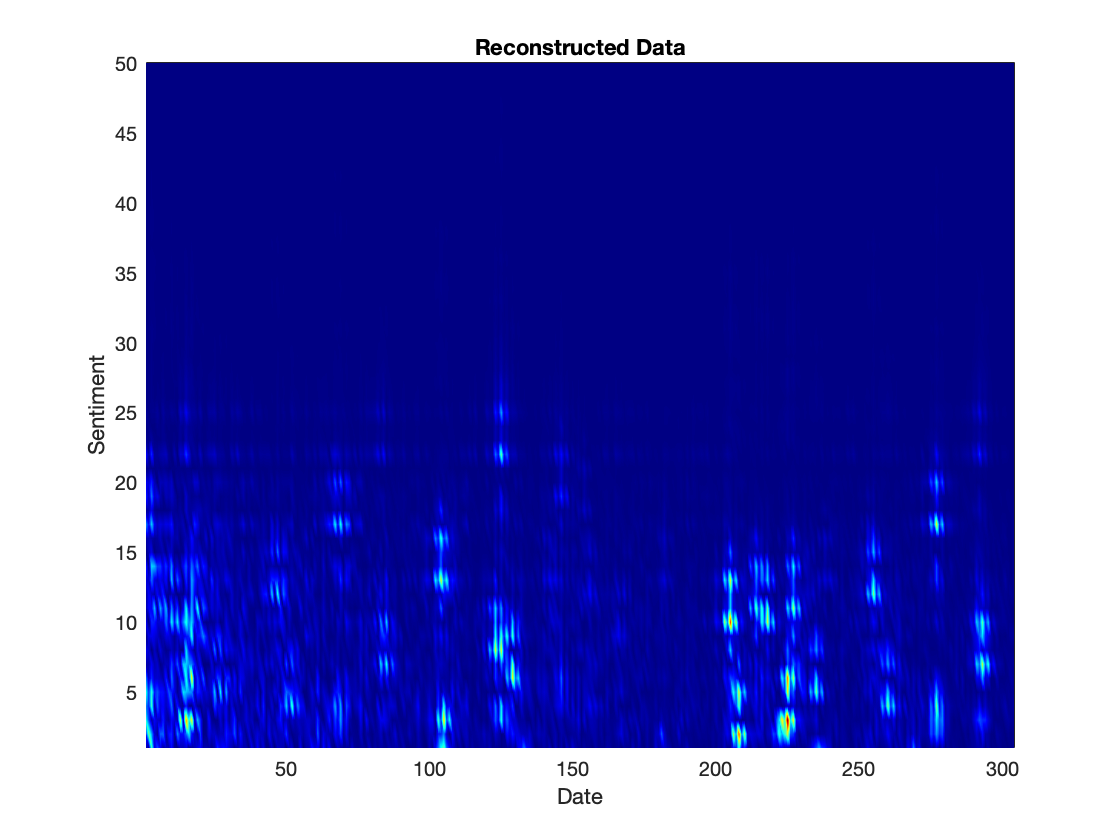


h9=figure;
axes9 = axes('Parent',h9,'FontSize',14,'FontName','Agency FB');
box(axes9,'on');
pcolor(abs(Vreconst))
shading('interp')
colormap(jet)
xlabel('Date')
ylabel('Sentiment')
title("Reconstructed Data")

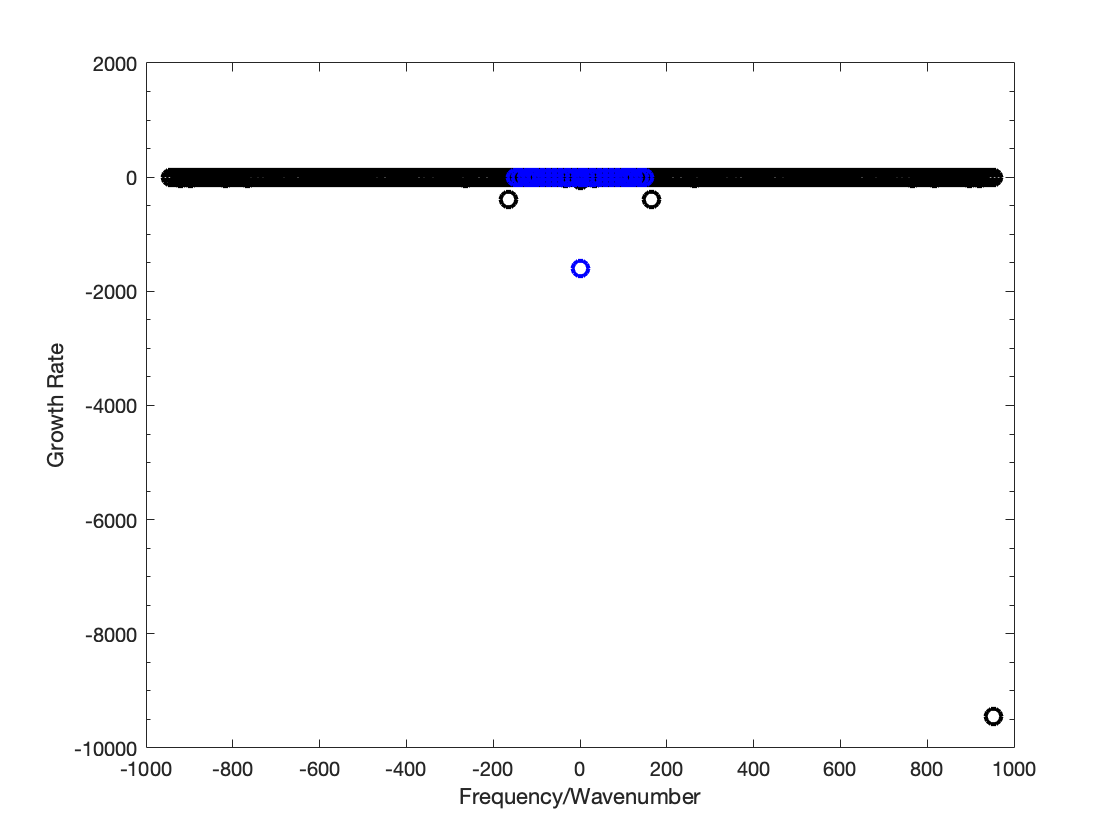



% Plot: frequency/wavenumber vs. amplitude, vs. growth rate
figure1 = figure;
axes1 = axes('Parent',figure1);
hold(axes1,'on');
box(axes1,'on');
semilogy(Frequencyt,GrowthRatet,'o','linewidth',2,'color','k','MarkerSize',8);
semilogy(Frequencyx,GrowthRatex,'o','linewidth',2,'color','b','MarkerSize',8);
set(axes1,'YMinorTick','on');
xlabel('Frequency/Wavenumber')
ylabel('Growth Rate')

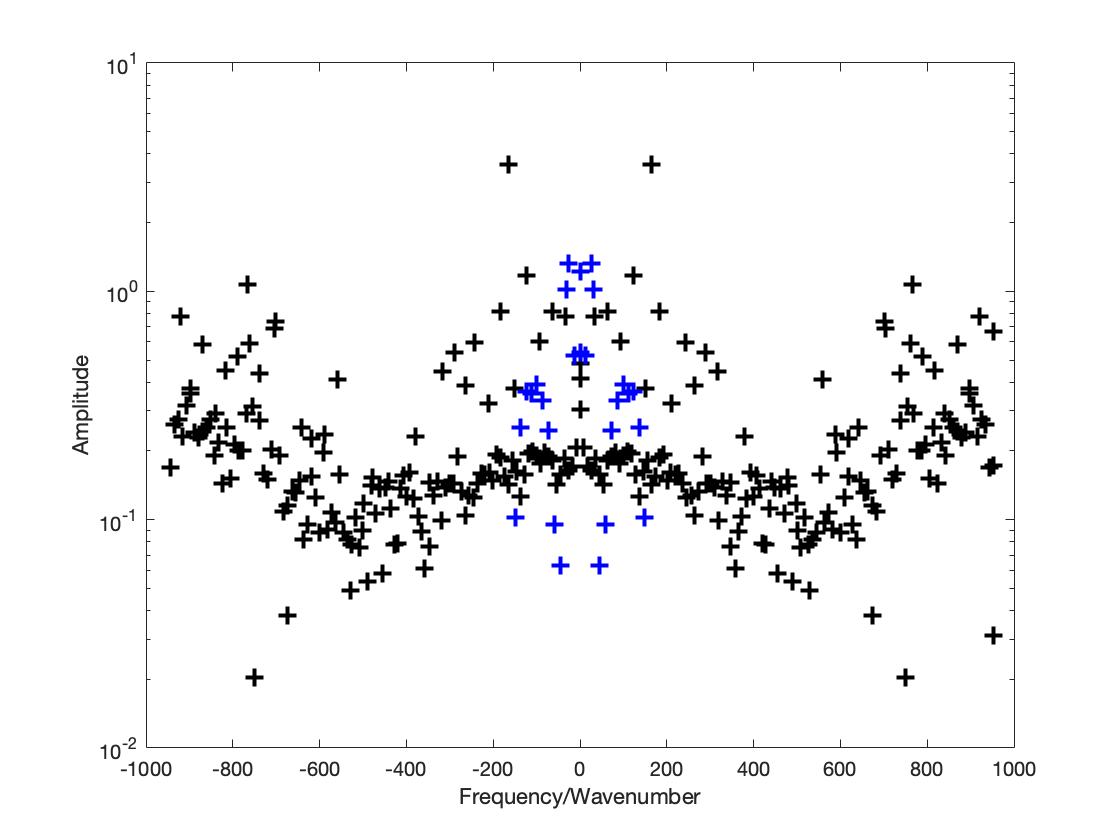

figure1 = figure;
axes1 = axes('Parent',figure1);
hold(axes1,'on');
box(axes1,'on');
semilogy(Frequencyt,Amplitudest,'+','linewidth',2,'color','k','MarkerSize',8);
semilogy(Frequencyx,Amplitudesx,'+','linewidth',2,'color','b','MarkerSize',8);
set(axes1,'YMinorTick','on','YScale','log');
xlabel('Frequency/Wavenumber')
ylabel('Amplitude')

### Conclusion

From the above experiments we can see that the snapshots (Data Matrix) is very sparse and STKD is not very sucessful in reconstrcting the snapshot. A few reasons could be/scope of improvement:

- Incorrect Choice of Space Variable

- Use of improved Sentiment Analyser

- Hypertuning parameters of STKD

- Restriction in Data Collection

- More weightage to Tweets from celebrities (eg:Elon Musk's tweet would be more important than any unknown individual)

Despite the result, this experiment was conducted to analyse if sentiments from twitter and News could potentially aid in predicting Volatile Markets. These experiments would be a base for further improvement and analysis.

#### Reference

[1] Kearney C, Liu S. Textual sentiment in finance: a survey of methods and models. Int Rev Financ Anal. 2014;33:171–85.

[2] Jiao P, Veiga A, Walther A. Social media, news media and the stock market. J Econ Behav Organ. 2020;176:63–90.